clear;
clc;

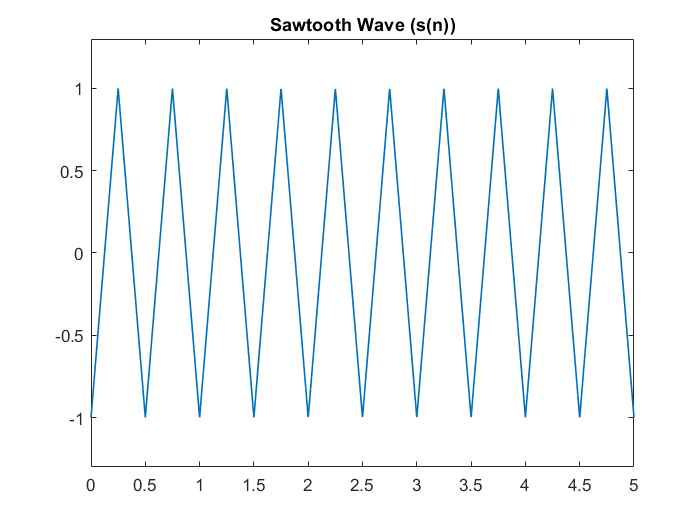

N = 5000; % Number of points
t = linspace(0,5,N)'; 
phi1=0;
phi2=0;
snr=10;
s = sawtooth(2*pi*2*t(1:N),0.5); 
n1 = 0.2*sin(2*pi*50*t(1:N/2)-phi1);
n2 = 0.3*sin(2* pi*100*t(N/2+1:N)-phi2); 
nwg = s - awgn(s,snr,'measured'); 
noise=nwg+[n1 ;n2];
xn = s + noise; 

figure;
plot(t,s,'LineWidth',1)
title('Sawtooth Wave (s(n))')
ylim([-1.3 1.3])

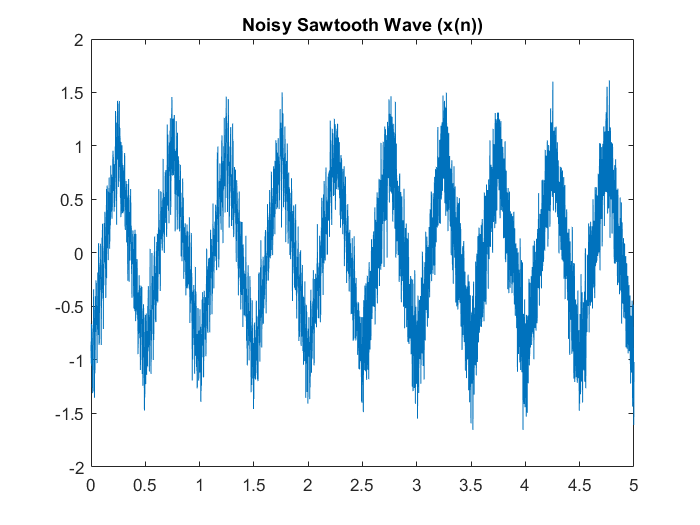


figure;
plot(t,xn)
title('Noisy Sawtooth Wave (x(n))')
ylim([-2 2])

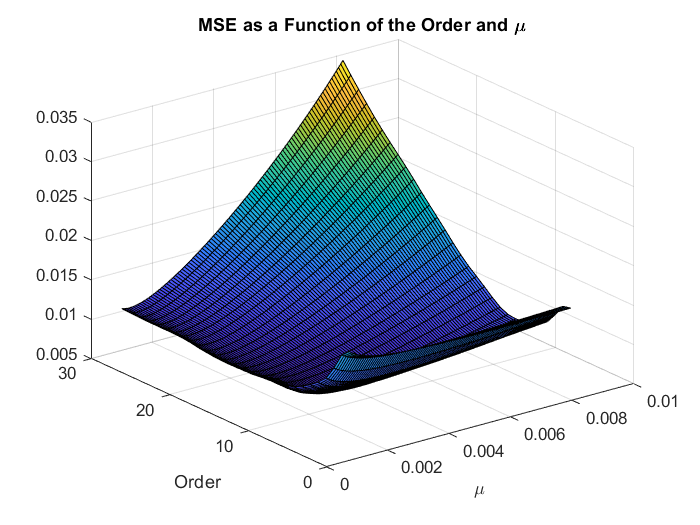

% 2.1 LMS Method
% 2.1.1 Exploring the Rate of Adaptation
a = 3;
phi1 = pi*(1/3); 
phi2 = pi*(1/6);

nref_1 = 0.2*sin(2*pi*50*t(1:N/2) + phi1);
nref_2 = 0.3*sin(2* pi*100*t(N/2+1:N) + phi2);

% Defining the reference signal
Reference_signal = a*(nwg + [nref_1 ; nref_2]);

% Iterating through a range of M and mu to find the optimum paramm
M_upper_limit = 30;
MSE_holder = NaN(M_upper_limit,100);
mu_upper_limit = round(2/(20*M_upper_limit*((xn'*xn)/length(xn))),4);
mu_range = linspace(0.001,mu_upper_limit,100);

for M=1:M_upper_limit
    for i = 1:100
        [e, ~, ~] = LMSFilter(xn', Reference_signal, mu_range(i), M);
        MSE_holder(M,i) = immse(e,s');
    end
end

% Plotting the results from the iterative process
figure
grid_M = 1:M_upper_limit;
surf(mu_range, grid_M, MSE_holder)
title('MSE as a Function of the Order and \mu')
xlabel('\mu')
ylabel('Order');


% Find LMS parameters that results in the minimum MSE
[min_paramm, index_paramm] = min(MSE_holder,[],2);
[minimum_MSE, corresponding_order] = min(min_paramm);
mu_constraint = index_paramm(corresponding_order)*(mu_upper_limit-0.001)/100 + 0.001;
disp(['Minimum Error = ' num2str(minimum_MSE) ' at M = ' num2str(corresponding_order) ' and mu = ' num2str(mu_constraint)])

Minimum Error = 0.0079063 at M = 10 and mu = 0.002584


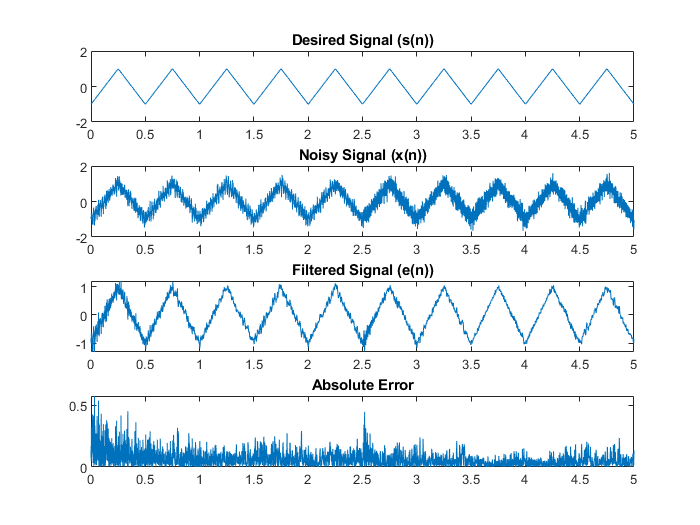


% Plotting the filtered signals at the optimum parameters
[e_opt_1, ~, ~] = LMSFilter(xn', Reference_signal, mu_constraint, corresponding_order);

figure ('Name','Adaptive Filtering')
subplot(4,1,1)
plot(t,s)
ylim([-2 2])
title('Desired Signal (s(n))')

subplot(4,1,2)
plot(t,xn)
title('Noisy Signal (x(n))')

subplot(4,1,3)
plot(t,e_opt_1)
title('Filtered Signal (e(n))')

subplot(4,1,4)
plot(t,abs(s'-e_opt_1))
title('Absolute Error')

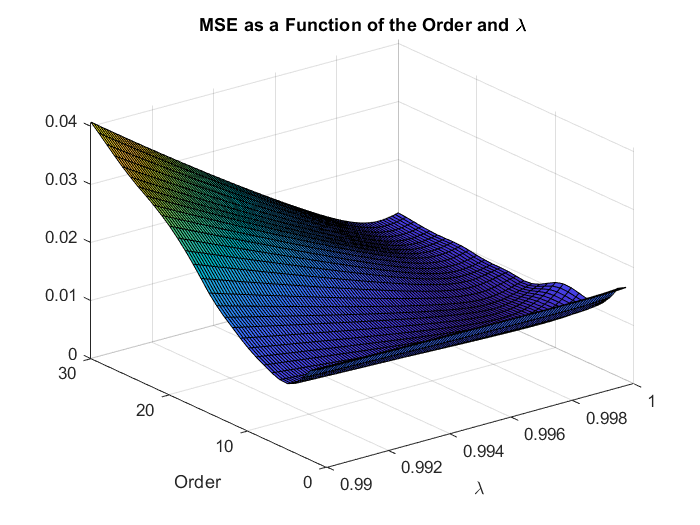

%% 2.2 RLS Method
%% 2.2.1 Exploring the Rate of Adaptation

% Iterating through a range of M and forgetting factors to find the optimum paramm
M_upper_limit = 30;
MSE_holder = NaN(M_upper_limit,100);
lambda_range = linspace(0.99,1,100);

for M=1:M_upper_limit
    for i = 1:100
        [e, ~, ~] = RLSFilter(xn', Reference_signal, lambda_range(i), M);
        MSE_holder(M,i) = immse(e',s');
    end
end

% Plotting the results from the iterative process
figure
grid_M = 1:M_upper_limit;
surf(lambda_range, grid_M, MSE_holder)
title('MSE as a Function of the Order and \lambda')
xlabel('\lambda')
ylabel('Order');



% Find LMS parameters that results in the minimum MSE
[min_paramm, index_paramm] = min(MSE_holder,[],2);
[minimum_MSE, corresponding_order] = min(min_paramm);
lambda_constraint = index_paramm(corresponding_order)*(0.01)/100 + 0.99; + 0.001;
disp(['Minimum Error = ' num2str(minimum_MSE) ' at M = ' num2str(corresponding_order) ' and lambda = ' num2str(lambda_constraint)])

Minimum Error = 0.0076037 at M = 10 and lambda = 0.9983


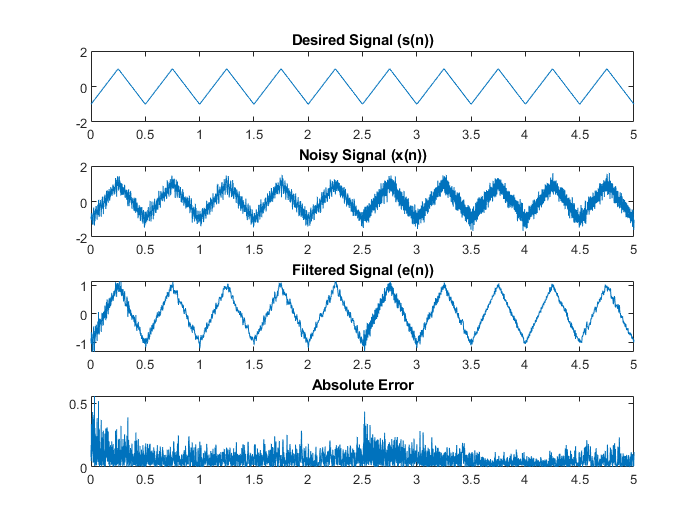


% Plotting the filtered signals at the optimum parameters
[e_opt, y_opt, w_opt] = RLSFilter(xn', Reference_signal, lambda_constraint, corresponding_order);


figure ('Name','Adaptive Filtering')
subplot(4,1,1)
plot(t,s)
ylim([-2 2])
title('Desired Signal (s(n))')

subplot(4,1,2)
plot(t,xn)
title('Noisy Signal (x(n))')

subplot(4,1,3)
plot(t,e_opt)
title('Filtered Signal (e(n))')

subplot(4,1,4)
plot(t,abs(s-e_opt))
title('Absolute Error')

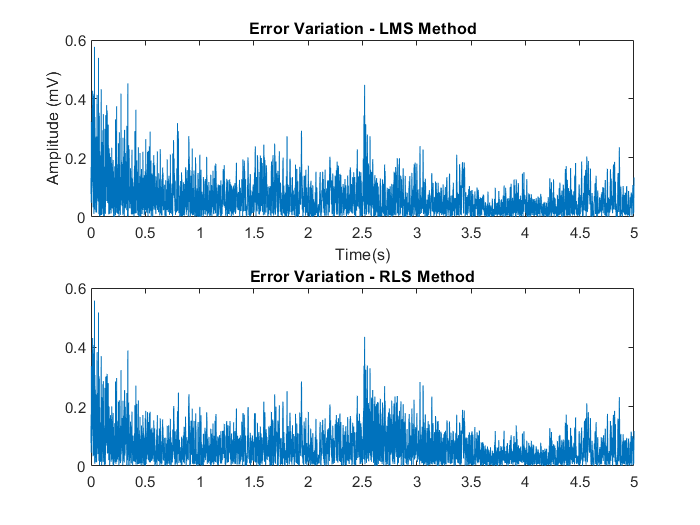

%% 2.2.2 Comparing the Performance of the LMS and RLS Algorithms
figure
subplot(2,1,1)
plot(t,abs(e_opt_1 - s'));
title('Error Variation - LMS Method')
xlabel('Time(s)')
ylabel('Amplitude (mV)');

subplot(2,1,2)
plot(t,abs(e_opt - s))
title('Error Variation - RLS Method');
linkaxes()


% Finding which one is better
error_RLS_less_LMS = abs(e_opt' - s') < abs(e_opt_1 - s');
total_error_RLS_less_LMS = sum(error_RLS_less_LMS);
percentage_cal = total_error_RLS_less_LMS*100/length(t); 
disp(percentage_cal)

   50.5600



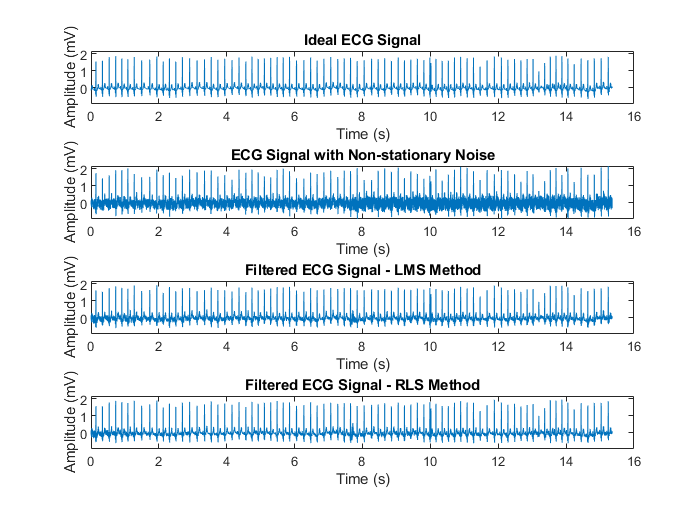

load('idealECG.mat')

% Mean normalizing the signal
idealECG = idealECG - mean(idealECG);

% Sampling frequency
f_s = 500;

t_range_ECG = linspace(0,length(idealECG)-1,length(idealECG))/f_s;

% Adding noise (Repeating the same procedure)
n_awg_new = idealECG - awgn(idealECG,10,'measured');

t_first_half_ecg = t_range_ECG(1:floor(length(t_range_ECG)/2));
t_second_half_ecg = t_range_ECG(floor(length(t_range_ECG)/2)+1:end);

% Generating the sinusoid noise
sin_noise_1 = 0.2*sin(2*pi*50*t_first_half_ecg);
sin_noise_2 = 0.3*sin(2*pi*100*t_second_half_ecg);
ns_noise_for_ideal_ECG = [sin_noise_1 sin_noise_2];

noisy_ECG_signal = idealECG + n_awg_new + ns_noise_for_ideal_ECG;

% Setting the parameters
a = 3;
phi_1 = pi*(1/6); 
phi_2 = pi*(1/3);

% Creating the reference signals
noise_for_ref_1 = 0.2*sin(2*pi*50*t_first_half_ecg + phi_1); 
noise_for_ref_2 = 0.3*sin(2*pi*100*t_second_half_ecg + phi_2); 
ref_ECG = a*(n_awg_new + [noise_for_ref_1 noise_for_ref_2]);


total_noise_signal = n_awg_new + ns_noise_for_ideal_ECG;

% Filtering using LMS and RLS
% Setting the optimum parameters used in previous parts
mu_optimum = mu_constraint;
lambda_optimum = lambda_constraint;
order_LMS = 20;
order_RLS = 26;

% LMS
[e_ECG_LMS, y_ECG_LMS, w_ECG_LMS] = LMSFilter(noisy_ECG_signal, ref_ECG, mu_optimum, order_LMS);

% RLS
[e_ECG_RLS, y_ECG_RLS, w_ECG_RLS] = RLSFilter(noisy_ECG_signal, ref_ECG, lambda_optimum, order_RLS);

figure('Name','Adaptive Filtering ECG')
subplot(4,1,1)
plot(t_range_ECG, idealECG)
title('Ideal ECG Signal');
xlabel('Time (s)')
ylabel('Amplitude (mV)');

subplot(4,1,2)
plot(t_range_ECG, noisy_ECG_signal)
title('ECG Signal with Non-stationary Noise')
xlabel('Time (s)')
ylabel('Amplitude (mV)');

subplot(4,1,3)
plot(t_range_ECG, e_ECG_LMS)
title('Filtered ECG Signal - LMS Method')
xlabel('Time (s)')
ylabel('Amplitude (mV)');

subplot(4,1,4)
plot(t_range_ECG, e_ECG_RLS)
title('Filtered ECG Signal - RLS Method')
xlabel('Time (s)')
ylabel('Amplitude (mV)');
linkaxes()